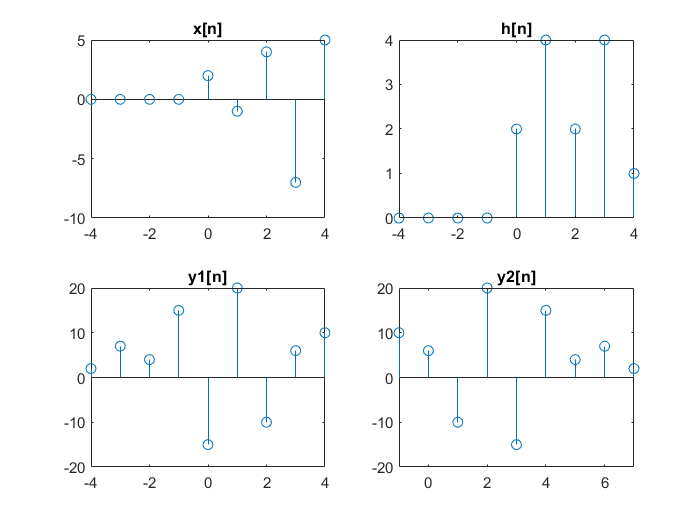

clc 
clear 
close all

o=5;p=-(o-1):1:o-1;
x1=func7(p);subplot(2,2,1);stem(p,x1);title('x[n]');
h1=func8(p);subplot(2,2,2);stem(p,h1);title('h[n]');
h2=func8(-p);
m=5;n=5;L=m+n-1;
x1e=zeros(1,L);
h2e=zeros(1,L);
y1=h2e;
x1e(1:m)=x1(o:2*o-1);
x1e(m+1:L)=0;
h2e(1:n)=h2(1:o);
h2e(n+1:L)=0;
for i=1:L
    y1(i)=0;
    for k=1:i
        y1(i)=y1(i)+h2e(k)*x1e(i-k+1);
    end
end
v=-4:1:4;
subplot(2,2,3);stem(v,y1);title('y1[n]');
x2=func7(3-p);
m=5;n=5;L=m+n-1;
x2e=zeros(1,L);
h1e=zeros(1,L);
y2=h1e;
x2e(1:m)=x2(4:8);
x2e(m+1:L)=0;
h1e(1:n)=h1(o:2*o-1);
h1e(n+1:L)=0;
for i=1:L
    y2(i)=0;
    for k=1:i
        y2(i)=y2(i)+h1e(k)*x2e(i-k+1);
    end
end
u=3-(m-1):1:((m-1)-1+(m-1)); %x:(-1:3) h:(0:4) hence y:(-1+0:4+3)
subplot(2,2,4);stem(u,y2);title('y2[n]');